##   Test Frame Search Process

Author: Michel Barbeau, Carleton University

Draft version: January 2, 2021

### Reading a File with the .c2 Extension

clear;
% name of ".c2" file
% FileName = '150426_0918.c2';
% FileName = 'test_minus_28.c2'; % NOK (32 errors) Not expected to work!
%FileName = 'test_minus_27.c2'; % OK
% FileName = 'test_minus_26.c2'; % OK
% FileName = 'test_minus_25.c2'; % OK
% FileName = 'test_minus_20.c2'; % OK
% FileName = 'test_minus_10.c2'; % OK
FileName = 'test.c2'; % no noise OK
fileID = fopen(FileName,'r');

The following three parameters (file name, type and frequency) are read, but not interpreted.

% read file name (14 characters)
fname=fread(fileID,[1 14],'char');
% read WSPR type (integer) 2="two minute mode"
type=fread(fileID,[1 1],'int');
% read frequency (double)
dfreq=fread(fileID,[1 1],'double');

The content of the file represents 120 seconds of signal samples that have been buffered, termed the *two minute mode*.  The sampling rate ($f_s$) is 375 samples per second (sps).  Hence there are $n=375 \cdot 120=45,000$ complex samples (in-phase and quadrature) read. Let $x_0 ,x_1 ,\ldotp \ldotp \ldotp ,x_{n-1}$ represent the discrete complex samples of two-minute channel data.

n=45000; % number of sambles (120 seconds of channel data)
fs=375; % sampling frequency
% read data (float)
buffer=fread(fileID,[2 n],'float');
% close the ".c2" file
fclose(fileID);

The in-phase and quadrature signals are respectively assigned to the MATLAB variables I and Q.

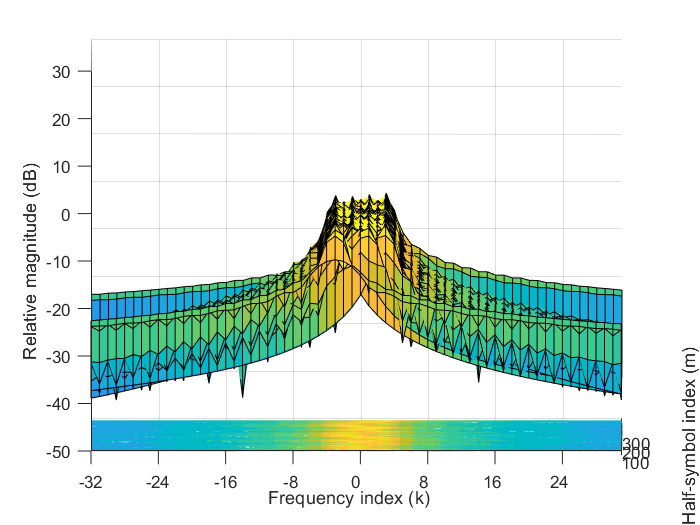

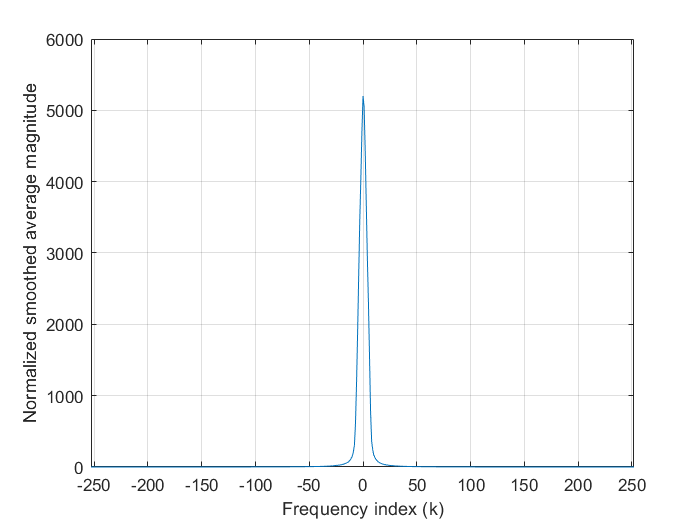

The number of candidates is 297
[index 6-Hz-SNR(dB)]
[-149 -6.96] [-147 -6.51] [-146 -6.68] [-145 -6.11] [-144 -6.32] [-143 -5.75] [-142 -5.90] [-141 -5.41] [-140 -5.61] [-139 -5.11] [-138 -5.26] [-137 -4.82] [-136 -5.02] [-135 -4.55] [-134 -4.72] [-133 -4.28] [-132 -4.48] [-131 -4.03] [-130 -4.19] [-129 -3.74] [-128 -3.91] [-127 -3.46] [-126 -3.60] [-125 -3.15] [-124 -3.29] [-123 -2.86] [-122 -2.98] [-121 -2.55] [-120 -2.65] [-119 -2.26] [-118 -2.38] [-117 -1.98] [-116 -2.07] [-115 -1.71] [-114 -1.83] [-113 -1.46] [-112 -1.55] [-111 -1.22] [-110 -1.33] [-109 -0.99] [-108 -1.08] [-107 -0.76] [-106 -0.87] [-105 -0.55] [-104 -0.63] [-103 -0.32] [-102 -0.41] [-101 -0.09] [-100 -0.15] [-99 0.16] [-98 0.10] [-97 0.41] [-96 0.37] [-95 0.69] [-94 0.66] [-93 0.96] [-92 0.93] [-91 1.23] [-90 1.23] [-89 1.50] [-88 1.48] [-87 1.77] [-86 1.77] [-85 2.03] [-84 2.01] [-83 2.28] [-82 2.28] [-81 2.53] [-80 2.51] [-79 2.78] [-78 2.77] [-77 3.03] [-76 3.01] [-75 3.28] [-74 3.27] [-73 3.55] [-72 3.53] [-

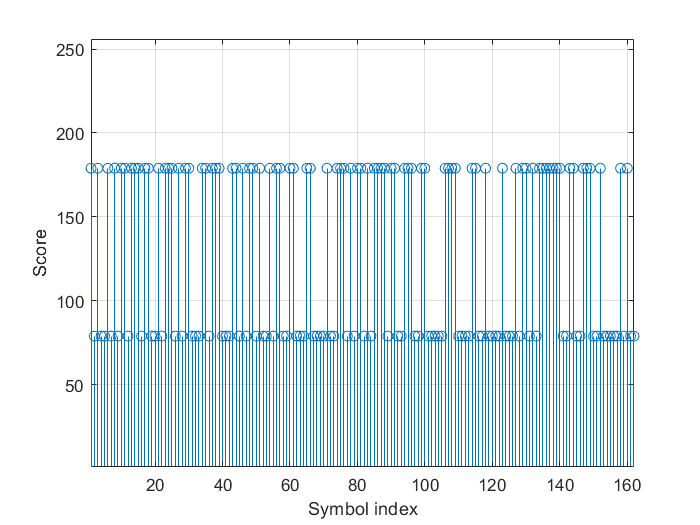

Scores first 12 channel symbols
 179  79  179  79  79  179  79  179  79  179  179  79 


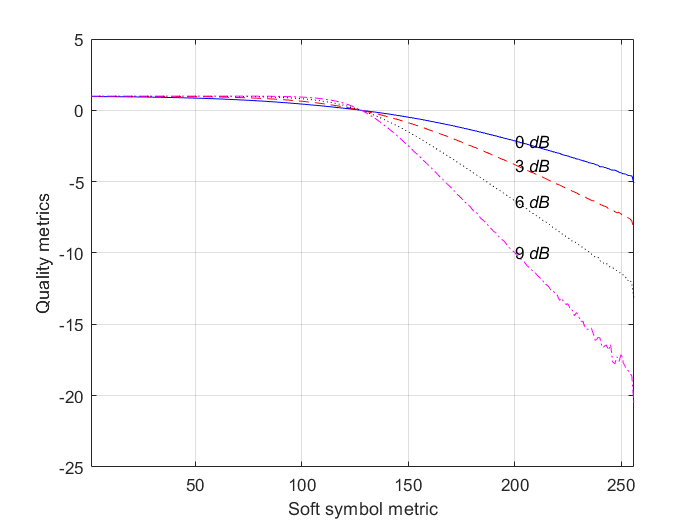

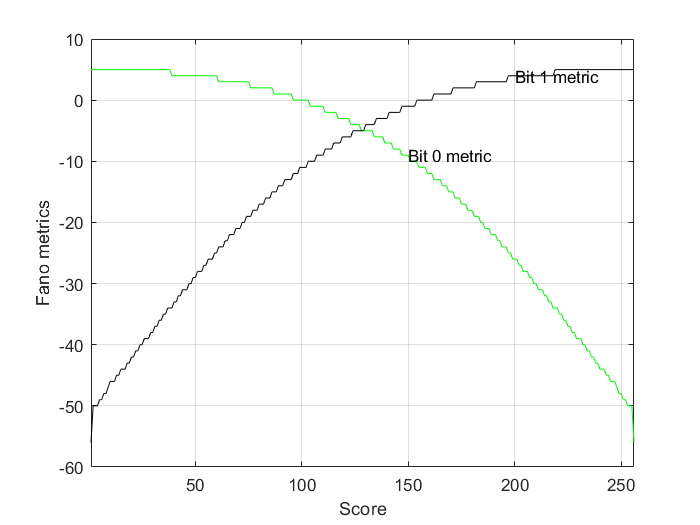

%Ahmad's Code
if not(libisloaded('wsprsim'))
   loadlibrary('wsprsim')
end
insig = libpointer('doublePtr', zeros(1,45000));
qdsig = libpointer('doublePtr', zeros(1,45000));
calllib('wsprsim', 'wsprfunc','VE3EMB FN25 30', 50, insig, qdsig)
%calllib('wsprsim', 'wsprfunc','K1ABC FN42 33', 50, insig, qdsig)

I=insig.val;
Q=-qdsig.val;

% in-phase
%I=buffer(1,:);
% quadrature
%Q=buffer(2,:);

K=32; % constraint
% message with K-1 zeros; Correspons to payload "VE3EMB FN25 30"
m=[1 1 0 1 0 1 0 0 0 0 1 0 1 1 0 0 0 1 1 1 0 0 1 1 1 1 1 0 1 0 1 1 0 0 1 1 1 0 1 0 0 1 1 1 0 1 1 1 1 0 zeros(1,K-1)];
[result, cycles, output, gamma, RMS] = framesearch(...
    I, Q, n, fs, 1, 1, 2, 16.25);

if result
    fprintf("Decoding failure; cycles=%d; gamma=%d; RMS=%2.2f!\n",cycles, gamma, RMS);
    return;
else
    fprintf("Decoding success; cycles=%d; gamma=%d; RMS=%2.2f!\n",cycles, gamma, RMS);
    present(output)
    if isequal(output,m)
        fprintf("With no errors!\n");
    else
       fprintf("With %d errors!\n", sum(output~=m));
    end
end

Decoding success; cycles=81; gamma=324; RMS=50.00!


th =      1     1     0     1     0     1     0     0     0     0     1     0     1     1     0     0     0     1     1     1     0     0     1     1     1     1     1     0     1     0     1     1     0     0     1     1     1     0     1     0     0     1     1     1     0     1     1     1     1     0


With no errors!
